**%Chapter 1**

%Defining Matrices
%Define the 3x3 matrix A with all 1's in the first row, all 2's in the second row,
%and all 3's in the 3rd row.
A = [1 1 1 ; 2 2 2; 3 3 3]
%Use the size() function to compute the number of rows and columns of matrix A.
%Store these quantities as variables numRows and numCols.
[numRows, numCols] = size(A)
%Use the eye() function to create the 4x4 identity matrix.  Store this matrix as I.
I = eye(4)
%Compute the transpose of the matrix A.  Store this transposed matrix as the matrix D.
D = A.'


%augmented matrices
%Create the coefficient matrix A.
A = [
    1,3,-2,0,2,0;
    2,6,-5,-2,4,-3;
    0,0,1,5,0,3;
    1,3,0,4,2,9
    ]

A =      1     3    -2     0     2     0
     2     6    -5    -2     4    -3
     0     0     1     5     0     3
     1     3     0     4     2     9


%Create the column matrix b of constants. Remember, to create a column matrix, the rows are separated
%by semicolons.
b = [
    0;
    -1;
    1;
    3
    ]

b =      0
    -1
     1
     3


%Create the augmented matrix [A | b|.  Store this augmented matrix in Ab.
Ab = [A b]

Ab =      1     3    -2     0     2     0     0
     2     6    -5    -2     4    -3    -1
     0     0     1     5     0     3     1
     1     3     0     4     2     9     3


%Use the rref() command to reduce the augmented matrix.  Store the reduced matrix in rowreducedAb, and
%store the pivot variables in pivotvarsAb.
[rowreducedAb, pivotvarsAb] = rref(Ab)

rowreducedAb =     1.0000    3.0000         0         0    2.0000         0         0
         0         0    1.0000         0         0         0         0
         0         0         0    1.0000         0         0         0
         0         0         0         0         0    1.0000    0.3333


pivotvarsAb =      1     3     4     6


%Warning:  Look carefully at the reduced augmented matrix.  If one of the pivot columns is the rightmost
%column, the system of linear equation has no solution and no further analysis is possible.

%Do you run into any difficulties?  Explain what is happening as a comment in your code.
%This matrix is not in echelon form, which makes it difficult at first glance to determine the pivot columns.
%upon rearranging you discover that the last column is not a pivot column.

%Use the size command to find the number of variables in the system of linear equations.  Store this number
%in numvars.
[numeqns, numvars] = size(A)

numeqns = 4

numvars = 6

%Use the size command to find the number of pivot variables.  Store this number in numpivotvars.
[numrows, numpivotvars] = size(pivotvarsAb)

numrows = 1

numpivotvars = 4

%Use subtraction to find the number of free variables in the solution to the system of linear equations.
%Store this number in numfreevars.
numfreevars = numvars - numpivotvars

numfreevars = 2

**%Chapter 2**

%Matrix Operations
%Create the matrices A, B, and C.
A = [1 2 0; -1 -2 3]
B = [-2 0 3; 1 3 1; 0 1 -1]
C = [3 1; 2 -1; -1 0]
%WARNING:  Matrix operations are only possible using matrices of the appropriate sizes.

%Find the scalar product of 2 times A.  Store this product in Ans1
Ans1 = 2*A
%Find the product of A and B.  Store this product in Ans2.
Ans2 = A*B
%Use the appropriate identity matrix to find the sum of Ans2 and AI.  Store this product in Ans3.
%Per Identity Rules, AI = A
Ans3 = Ans2 + A
%Use the appropriate identity matrix to find CI minus 2 times the transpose of Ans2.  Store
%this product in Ans4.
%Per Identity Rules, CI = C
Ans4 = C - 2 * Ans2.'



%inverse of a square matrix
%Create the square matrix A.
A = [1 0 -1; 2 1 -5; 1 -1 0]
%Use the format command view values as rational numbers rather than decimals.
format rat
%Create the augmetned matrix [A | I] using the apprpopriately sized identity matrix.  Store this
%matrix in AugA
AugA = [A eye(3)]
%Use the rref() command to reduce the augmented matrix.  Store the reduced matrix in rowreducedAugA.
%Store the pivot variables in pivotvarsAugA.
[rowreducedAugA, pivotvarsAugA] = rref(AugA)
%Retrieve the inverse of matrix A from the reduced augmented matrix [I | Ainv]. Store the inverse
%matrix in Ainv1.
Ainv1 = rowreducedAugA(:, 4:6)
%Use the inv() command to find the inverse of matrix A.  Store the inverse matrix in Ainv2.
Ainv2 = inv(A)


%solve systems of linear equations
%Create the coefficient matrix.  Store the coefficient matrix in A.
A = [-2 1 2; 1 3 2; 3 -1 1]
% A = [-2 1 2; 1 3 2; -1 4 4]
%Create the column matrix of constants.  Store the column matrix of constants in b.
b = [0; -4; 3]
%Use the inv() command to find the inverse of the matrix A.  Store the inverse matrix in invA.
invA = inv(A)
%Find the solution to the linear system of equations using the inverse matrix, if the inverse matrix
%exists.  If the inverse matrix exists, store the solution to the linear system of equations in x.
x = invA*b
%Before submitting your solution, consider repeating the work above with the coefficient matrix A = [-2 1 2; 1 3 2; -1 4 4].  Do you run into any difficulties or errors when finding the solution?  Explain what is happening as a comment in your code.
%The alternative matrix has a determinant of 0, and thus no inverse.


%LU Decomposition
%Create the coefficient matrix A and and the column matrix b of constants.
A = [1 2 3; 3 0 -1; 2 -1 1]

A =      1     2     3
     3     0    -1
     2    -1     1


b = [9 ; 3; 8]

b =      9
     3
     8


%Use the lu() command to find the LU decomposition of A, storing the lower and upper matrices
%in L and U, respectively.
[ L, U] = lu(A)

L =     0.3333    1.0000         0
    1.0000         0         0
    0.6667   -0.5000    1.0000


U =     3.0000         0   -1.0000
         0    2.0000    3.3333
         0         0    3.3333


%Solve the system of linear equations Ax=b using the LU decomposition.  Store the intermediary
%solution in y.  Store the solution for x in x1.
y = L\b

y =      3
     8
    10


x1 = U\y

x1 =     2.0000
   -1.0000
    3.0000


%Check that the solution x1 matches that found by directly using the backslash operator to solve
%the system Ax=b.  Use the backslash operator to solve Ax=b in one step, storing the solution in x2.
x2 = A\b

x2 =     2.0000
   -1.0000
    3.0000


**%Chapter 3**

%DOT Product
%Create the row vectors a=[1, -2, 0, 7] and b=[-3, -1, 5, 0].
a=[1 -2 0 7]
b=[-3 -1 5 0]
%Create the column vectors c=[3, 1, 4, -2] and d=[0, -2, 2, 1].
c=[3; 1; 4; -2]
d=[0; -2; 2; 1]
%Use the dot() command to find the dot product of vectors a and b.  Store this value in g1. 
g1 = dot(a, b)
%Use matrix multiplication to find the dot product of vectors a and b.  Store this value in g2.
g2 = a * b.'
%Use the dot() command to find the dot product of vectors c and d.  Store this value in h1. 
h1 = dot(c, d)
%Use matrix multiplication to find the dot product of vectors c and d.  Store this value in h2.
h2 = c.' * d

%In this activity you will find the cross product of two vectors in 3-space and apply appropriate
%MATLAB commands to find the area of a parallelepiped (cross(), dot(), and abs()).
%Define the three vectors u=[1, 0, -4], v=[3, -3, 1], and w=[0, 2, 1].
u = [1, 0, -4]

u =        1              0             -4       


v = [3, -3, 1]

v =        3             -3              1       


w = [0, 2, 1]

w =        0              2              1       


%Find the cross product of u and w.  Store it in a1.
a1 = cross(u, w)

a1 =        8             -1              2       


%Find the cross product of w and u.  Store it in a2.  Reversing the order of the cross product
%results in a vector of the same length but opposite direction.  Note that a2 = -1(a1).
a2 = cross(w, u)

a2 =       -8              1             -2       


%Find the volume of the parallelepiped determined by vectors u, v, and w.  Store this value in z.
z = abs(dot(u, cross(v,w)))

z =       29       




%finding area of triangle
A = [ 6, 9, -8]

A =        6              9             -8       


B = [ 0, -9, -1]

B =        0             -9             -1       


C = [-8, -9, 2]

C =       -8             -9              2       



pos_AB = B-A

pos_AB =       -6            -18              7       


pos_AC = C-A

pos_AC =      -14            -18             10       



AB_times_AC = cross(pos_AB, pos_AC)

AB_times_AC =      -54            -38           -144       


%calculate magnitude using norm()
area_paralellogram = norm(AB_times_AC)

area_paralellogram =    25822/163   


area_triangle = area_paralellogram/2

area_triangle =    12911/163   



%scalar triple product
u = [4,9,-8]

u =        4              9             -8       


v = [8,0,2]

v =        8              0              2       


w = [5,0,1]

w =        5              0              1       



v_times_w = cross(v, w)

v_times_w =        0              2              0       


scalar_triple_prod = dot(u, v_times_w)

scalar_triple_prod =       18       


%take magnitude to find volume of parallelepiped
vol_paral = norm(scalar_triple_prod)

vol_paral =       18       


%In this activity you will use the det() command to find the determinant of a matrix.
%Consider using the command "format rat" to view the matrix and determinant using rational numbers.
%Create the matrix A.
A = [
4, 1/2, 0, -1, 3; 
-1, 0, 1, -2, 1/2;
3, 1, -1, 0, 1;
0, -1/2, 1, 1, 0;
1, 0, 3, 0, 3;
]
%Use the det() command to find the determinant of A.  Store this value in detA.
detA = det(A)

%solving for equation of a plane
%given set (0, 0, 2), (0, 6, 0), (2, 3, 1)
syms x y z 
A = [
x, y, z, 1;
0, 0, 2, 1;
0, 6, 0, 1;
2, 3, 1, 1
]
Adet = det(A, 'Algorithm', 'minor-expansion')

A = [
-7,-2,-3,9;
12, 10, 8, 5;
1, -8, 6, -5;
1, -8, 6, -5;
-28, -8, -12, 36
]
%find echelon form for easy determination of determinant
rref(A)
% detA = det(A)

%cramers rule to solve a system of equations
%Note:  Cramer's Rule only applies to systems of linear equations 
%with invertible square
%coefficient matrices.
%Create the coefficient matrix A and column matrix of constants b.
A = [
    1 1 -1;
    3 -2 1;
    1 3 -2
    ]   

b = [
    6;
    -5;
    14
     ]
%Initialize the matrices A1, A2, and A3 as matrix A.
A1 = A
A2 = A
A3 = A
%Replace the appropriate columns in A1, A2, and A3 with the column vector of constants b. 
A1(:,1)=b
A2(:,2)=b
A3(:,3)=b
%Find the solution for x1, x2, and x3 using ratios of determinants.
x1 = det(A1)/det(A)
x2 = det(A2)/det(A)
x3 = det(A3)/det(A)

**Chapter 4**

%A vector is an ordered n-tuple that can be represented as a row or column vector.  Here the vectors are rows.
v1 = [5 4 2]

v1 =      5     4     2


v2 = [2 1 -1]

v2 =      2     1    -1


v3 = [3 1 -3]

v3 =      3     1    -3


v4 = [0 2 6]

v4 =      0     2     6



%To determine if this set of vectors spans 3-space, first create a matrix C consisting of the column vectors.
%Note, the vectors were created as row vectors.  Use the dot-tic operator to make them column vectors.
%Alternatively, you can create the vectors as column vectors to avoid using the dot-tic operator.
C = [v1.' v2.' v3.' v4.']

C =      5     2     3     0
     4     1     1     2
     2    -1    -3     6



%For vectors in 3-space, the reduced matrix will have three pivot columns if the vectors span 3-space.
reducedC = rref(C)

reducedC =     1.0000         0   -0.3333    1.3333
         0    1.0000    2.3333   -3.3333
         0         0         0         0


%For this example, the reduced matrix has only two pivot columns, so the set of vectors does not span 3-space.

%Consider the vector u=[2 1 1].  To determine if u is in the span of the given vectors, create an
%augmented matrix [C|u].  
u = [2 1 1]

u =      2     1     1


Cu = [C u.' ]

Cu =      5     2     3     0     2
     4     1     1     2     1
     2    -1    -3     6     1


%If a solution to the system Cx=u exists, then u is in the span of the vectors.
reducedCu = rref(Cu)

reducedCu =     1.0000         0   -0.3333    1.3333         0
         0    1.0000    2.3333   -3.3333         0
         0         0         0         0    1.0000


%For this example, the reduced matrix has no solution to the system Cx=u, so u is not in the span of the vectors.

%Enter vectors v1, v2, v3, and v4 as row vectors.
v1 = [1 0 1 1]

v1 =      1     0     1     1


v2 = [2 -2 3 2]

v2 =      2    -2     3     2


v3 = [1 -1 1 0]

v3 =      1    -1     1     0


v4 = [0 -1 1 1]

v4 =      0    -1     1     1



%Create a matrix A consisting of these vectors as column vectors.
A = [v1.' v2.' v3.' v4.']

A =      1     2     1     0
     0    -2    -1    -1
     1     3     1     1
     1     2     0     1


%For vectors in 4-space, the reduced matrix will have four pivot columns if the vectors span 4-space.
%Find the reduced matrix, storing it in reducedA.  Do the vectors span 4-space? 
%No they span 3-space since there are 3 pivot columns.
reducedA = rref(A)

reducedA =      1     0     0    -1
     0     1     0     1
     0     0     1    -1
     0     0     0     0


%Create the vector w=[2 1 1 1].
w = [2 1 1 1]

w =      2     1     1     1


%Create an augmented matrix [A|w], storing it in Aw.
Aw = [A w.']

Aw =      1     2     1     0     2
     0    -2    -1    -1     1
     1     3     1     1     1
     1     2     0     1     1


%Find the reduced matrix, storing it in reducedAw.  Is w is in the span of the vectors?
%No, the last column is a pivot column so there is no solution.
reducedAw = rref(Aw)

reducedAw =      1     0     0    -1     3
     0     1     0     1    -1
     0     0     1    -1     1
     0     0     0     0     0


%Recall vectors are ordered n-tuples that can be represented as row or column vectors. 
v1 = [2 -1 -1 1 3]

v1 =      2    -1    -1     1     3


v2 = [-3 2 5 1 3]

v2 =     -3     2     5     1     3


v3 = [7 -4 -7 1 3]

v3 =      7    -4    -7     1     3



%Create a matrix C with the given vectors placed in the columns of C.
C = [v1.' v2.' v3.']

C =      2    -3     7
    -1     2    -4
    -1     5    -7
     1     1     1
     3     3     3



%Create the appropriately sized itendity matrix, storing it in I.
I = eye(5)

I =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1



%Augment C with the identity matrix.
augC = [C I]

augC =      2    -3     7     1     0     0     0     0
    -1     2    -4     0     1     0     0     0
    -1     5    -7     0     0     1     0     0
     1     1     1     0     0     0     1     0
     3     3     3     0     0     0     0     1



%Row reduce augC.  
B = rref(augC)

B =     1.0000         0    2.0000         0         0   -0.1667         0    0.2778
         0    1.0000   -1.0000         0         0    0.1667         0    0.0556
         0         0         0    1.0000         0    0.8333         0   -0.3889
         0         0         0         0    1.0000   -0.5000         0    0.1667
         0         0         0         0         0         0    1.0000   -0.3333



%The pivot columns of the reduced matrix are used to identify which of the original vectors 
%are included in the basis, along with which columns of the identity matrix are included in the basis. 

%Create a matrix containing the basis vectors.  For this example, the first two vectors, namely v1 and v2,
%are linearly independent vectors from the given set.  Those two vectors combined with the 1st,
%2nd, and 4th columns of the identity matrix form a linearly indpendent set of vectors that spans 5-space.
BasisMatrix = [v1.' v2.' I(:,1) I(:,2) I(:,4)]

BasisMatrix =      2    -3     1     0     0
    -1     2     0     1     0
    -1     5     0     0     0
     1     1     0     0     1
     3     3     0     0     0


%Each basis can be represented by a matrix whose columns are the vectors in the basis.
B = [2 -4; -4 -6]

B =      2    -4
    -4    -6


C = [4 2; -1 3]

C =      4     2
    -1     3



%To find the change of coordinates matrix from basis B to basis C, set up the augmented
%matrix [C | B].
augCB = [C B]

augCB =      4     2     2    -4
    -1     3    -4    -6



%Row reduce the augmented matrix to get [I | P_BtoC].
temp = rref(augCB)

temp =      1     0     1     0
     0     1    -1    -2



%The change of coordinates matrix from basis B to basis C is the matrix that appears to the 
%right of the identity matrix in the augmented matrix.
P_BtoC = temp(:,3:4)

P_BtoC =      1     0
    -1    -2


%Enter the matrix, storing it in C.
C = [
    -1 2 0 4 5 -3;
    3 -7 2 0 1 4;
    2 -5 2 4 6 1;
    4 -9 2 -4 -4 7
    ]

C =     -1     2     0     4     5    -3
     3    -7     2     0     1     4
     2    -5     2     4     6     1
     4    -9     2    -4    -4     7


%Find the rank of the matrix C.  Store this value in rankC.
rankC = rank(C)

rankC = 2

%Find a basis of rational numbers for the null space of C. Store this in the matrix nullbasisC.
nullbasisC = null(C, 'r')

nullbasisC =      4    28    37   -13
     2    12    16    -5
     1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


%You should confirm that the dimension of the null space of C plus the rank of C 
%equals the number of columns in C.
ans = rankC + rank(nullbasisC)

ans = 6

%Create the augmented matrix D, whose columns are the ordered basis of C followed 
%by the image of the ordered basis of B.
D = [1 2 3 7; 4 3 -1 -1]

D =      1     2     3     7
     4     3    -1    -1


%Row reduce the augmented matrix to get [I | T_BtoC].  Use "format rat" to view values
%as rational numbers, if desired.
temp = rref(D)

temp =     1.0000         0   -2.2000   -4.6000
         0    1.0000    2.6000    5.8000


format rat
T_BtoC = temp(:,3:4)

T_BtoC =      -11/5          -23/5     
      13/5           29/5     


**Chapter 5**

    %The standard matrix A that rotates a point 45 degrees counterclockwise about the origin is given below.
A = [cos(pi/4) -sin(pi/4); sin(pi/4) cos(pi/4)]

A =      985/1393      -985/1393  
     985/1393       985/1393  



%Create a matrix S containing the points of the unit square as the columns.  Order the points as they
%would be traversed when drawing the edges of the square, repeating the starting point so that the 
%drawing starts and ends there.
S = [0 1 1 0 0; 0 0 1 1 0]

S =        0              1              1              0              0       
       0              0              1              1              0       


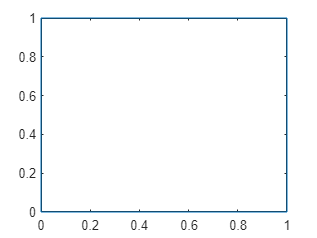


%Plot the unit square.
plot(S(1,:), S(2,:))


%Perform matrix multiplication to transform each of the points in S.
T1 = A*S

T1 =        0            985/1393         *           -985/1393         0       
       0            985/1393      1393/985        985/1393         0       


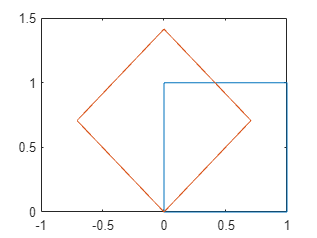


%Plot the original unit square and the transformed unit square.
plot(S(1,:), S(2,:), T1(1,:), T1(2,:))

%Creat the standard matrix A that rotates a point 60 degrees counterclockwise about the origin.
A = [
    cos(pi/3) -sin(pi/3);
    sin(pi/3) cos(pi/3)
    ]

A =        1/2        -1170/1351  
    1170/1351         1/2     


%Create a matrix S containing the points of the triangle as the columns.
S = [
    0 1 3 0;
    0 1 0 0
    ]

S =        0              1              3              0       
       0              1              0              0       


%Perform matrix multiplication to transform each of the points in S.  Store this in T1.
T1 = A*S

T1 =        0           -780/2131         3/2            0       
       0            780/571       1351/520          0       


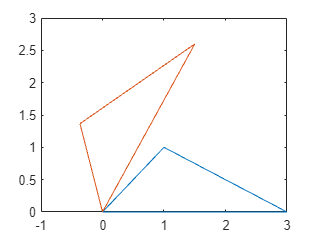

%Plot the original triangle and the transformed triangle in a single graph.
plot(S(1,:), S(2,:), T1(1,:), T1(2,:))

%Do you run into any difficulties?  Explain what is happening as a comment in your code.
%Initially I had to look up the radian value of 60 degrees, otherwise no. Matrix A is used to determine rotation
%about origin while Matrix S provides a plot of the points. Multiplying them transforms the points based upon the 
%values of Matrix A. 


**Chapter 6**

%In this activity you will find the eigenvalues and eigenvectors of a square matrix.

%Consider the following matrix.
A = [3 1 0; 0 3 1; 0 0 3]

A =      3     1     0
     0     3     1
     0     0     3



%Use the command poly() to find the characteristic polynomial.
CharacteristicPoly = poly(A)

CharacteristicPoly =      1    -9    27   -27



%Use the command roots() to find the eigenvalues.
eigenvalues = roots(CharacteristicPoly)

eigenvalues =    3.0000 + 0.0000i
   3.0000 - 0.0000i
   3.0000 + 0.0000i



%The eig() command returns diagonal matrix D of eigenvalues and matrix V whose 
%columns are the corresponding eigenvectors.  For example, the value on the diagional
%in the first column of D is the eigenvalue associated with the eigenvector in the first 
%column of V.  The eigenvectors in V are normalized, each having a magnitude of 1.
[V, D] = eig(A)

V =     1.0000   -1.0000    1.0000
         0    0.0000   -0.0000
         0         0    0.0000


D =      3     0     0
     0     3     0
     0     0     3


%Enter the matrix C.
C = [ 6 3 -8;
      0 -2 0;
      1 0 -3
    ]


%Find the coefficients of the characteristic polynomial.  Store them in PolyCoeffs.
PolyCoeffs = poly(C)
%Use the command roots() to find the eigenvalues.  Store them in evals.
evals = roots(PolyCoeffs)
%Use the eig() command.  Store the eigenvalues in matrix eigDiag.  Store the associated
%eigenvectors in eigV.
[V, D] = eig(C)
eigDiag = D
eigV = V

C =      6     3    -8
     0    -2     0
     1     0    -3


PolyCoeffs =      1    -1   -16   -20


evals =    5.0000 + 0.0000i
  -2.0000 + 0.0000i
  -2.0000 - 0.0000i


eigDiag =      5
    -2
    -2


% Finding the eigenbasis for any matrix 

A = [
    7 -8 -8;
    0 3 0;
    4 -8 -5
    ]

A =        7             -8             -8       
       0              3              0       
       4             -8             -5       


%V is corresponding eigenvectors and D is eigenvalues
[V, D] = eig(A)

V =     2584/2889       985/1393       963/3230  
       0              0            963/1292  
    1292/2889       985/1393      -963/1615  


D =        3              0              0       
       0             -1              0       
       0              0              3       



%notice how the Eigenvalue in matrice D is the diagonal, with the algebraic
%multiplicity being the occurrence. i.e 4 occurs 2 times, (4 - lambda)^2
% of form (A - xI)
A = (A-3*eye(3))

A =        4             -8             -8       
       0              0              0       
       4             -8             -8       



A = null(A,'rational')

A =        2              2       
       1              0       
       0              1       


A = [1 1; -2 4]
[P, D] = eig(A)

%Indirectly find A^5 using P and D.  The command power(D,5) raises every element in the diagonal matrix D 
%to the fifth power.  
A5indirectly = P*power(D,5)*inv(P)

%The same result can be found directly, but the direct method is not computationally practical for higher powers.
A5directly = A^5

%Enter matrix C.
C = [
    1 2 2;
    2 1 2;
    2 2 1]
%Use the eig() command to find the matrix P that diagonalizes C and the resulting diagonal 
%matrix D.  Store these in P and D, respectively.
[P, D] = eig(C)
%Indirectly find C^4, using P and D, and using the power() command on D.  Store the result in C4.
C4 = P*power(D,4)*inv(P)

**Chapter 7**

%Consider the column vector v.  The norm() command is used to find the Euclidean norm,
%the 4-norm, and the infinity-norm.
v = [-4; 3]

v =     -4
     3


two_norm = norm(v, 2)

two_norm = 5

four_norm = norm(v, 4)

four_norm = 4.2846

infinity_norm = norm(v, Inf)

infinity_norm = 4


%Consider the matrix A.  The norm() command is used to find the Frobenius norm.
A = [1/sqrt(6) 0; -2/sqrt(6) 1/sqrt(6)] 

A =     0.4082         0
   -0.8165    0.4082


fro_norm = norm(A, 'fro')

fro_norm = 1

%To find the Euclidean distance between two vectors, find the 2-norm of the difference of 
%those vectors.  Enter column vectors u and v.  Then use the norm() command to find d(u,v), storing 
%it in dist_uv.
u = [
    4;
    3
    ]
v = [
    -4;
    -12
    ]

dist_uv = norm(u-v)
%To find the distance between two matrices with respect to the Frobenius inner product, 
%find the Frobenius norm of the difference of those matrices.  Enter matrices A and B.  
%Then use the norm() command to find d(A,B), storing it in dist_AB.
A = [
    3 -7 4 3;
    -2 4 -5 0
    ]
B = [
    1 -7 2 5;
    0 0 -5 2
    ]

dist_AB = norm(A-B , 'fro')

%Calculate Orthogonal Basis using Gram-Schmidt
U_1 = [-2 0; -2 -1]
U_2 = [0 -18; 0 0]
U_3 = [ -1 2; 0 4]

V_1 = U_1

V_2 = U_2 - sum(dot(U_2,V_1)/dot(V_1,V_1)) * V_1

V_3 = U_3 - (sum(dot(U_3, V_1))/sum(dot(V_1, V_1))) * V_1 - (sum(dot(U_3, V_2))/sum(dot(V_2, V_2))) * V_2

%Use the qr() command to find the QR factorization of A, where Q is an orthogonal matrix
%and R is an upper triangular matrix. 
A = [-2 0 3; 1 3 1; 0 1 -1]
[Q, R] = qr(A)

%Verify QR=A.
checkA = Q*R

B = [ 1 0 3 -1;
    -2 1 0 5;
    0 0 1 7]

B =      1     0     3    -1
    -2     1     0     5
     0     0     1     7



[QB, RB] = qr(B)

QB =    -0.4472    0.8944         0
    0.8944    0.4472         0
         0         0    1.0000


RB =    -2.2361    0.8944   -1.3416    4.9193
         0    0.4472    2.6833    1.3416
         0         0    1.0000    7.0000



checkB = QB * RB

checkB =     1.0000    0.0000    3.0000   -1.0000
   -2.0000    1.0000    0.0000    5.0000
         0         0    1.0000    7.0000


%Consider the matrix A.
A = [1 -2; 0 1; 1 0]

A =      1    -2
     0     1
     1     0



%The command svd() returns three matrices, namely the mxm orthogonal matrix U, the mxn 
%diagonal matrix S, and the nxn orthogonal matrix V, the singular value decomposition
%of A which satisfies A=USV'.
[U, S, V] = svd(A)

U =     0.9129   -0.0000   -0.4082
   -0.3651    0.4472   -0.8165
    0.1826    0.8944    0.4082


S =     2.4495         0
         0    1.0000
         0         0


V =     0.4472    0.8944
   -0.8944    0.4472



%Verify that the appropriate product of the matrices found using the svd() command
%results in the matrix A.  
checkA = U*S*V.'

checkA =     1.0000   -2.0000
    0.0000    1.0000
    1.0000    0.0000



%use sym() to convert to radicals
sym(U)

$$ans = \left(\begin{array}{ccc} \frac{\sqrt{5}\,\sqrt{6}}{6} & -\frac{3}{18014398509481984} & -\frac{\sqrt{6}}{6}\\ -\frac{\sqrt{2}\,\sqrt{15}}{15} & \frac{\sqrt{5}}{5} & -\frac{\sqrt{2}\,\sqrt{3}}{3}\\ \frac{\sqrt{30}}{30} & \frac{2\,\sqrt{5}}{5} & \frac{\sqrt{6}}{6} \end{array}\right)$$

sym(S)

$$ans = \left(\begin{array}{cc} \sqrt{6} & 0\\ 0 & 1\\ 0 & 0 \end{array}\right)$$

sym(V)

$$ans = \left(\begin{array}{cc} \frac{\sqrt{5}}{5} & \frac{2\,\sqrt{5}}{5}\\ -\frac{2\,\sqrt{5}}{5} & \frac{\sqrt{5}}{5} \end{array}\right)$$

**Chapter 8**

%Consider the matrix A.  Since A is not a square matrix the inverse does not exist.  However,
%the pseudoinverse of A will exist.
A = [1 -2; 0 1; 1 0]

%The command pinv() returns the pseudoinverse of the matrix A.
B = pinv(A)

%Enter the matrix B.
B = [1 2 0;
    -1 -2 3]
%Find the pseudoinverse of the matrix B.  Store in in Bpinv.
Bpinv = pinv(B)
%Check that B=B*Bpinv*B.  Store the product in Bcheck.
Bcheck = B*Bpinv*B

A = [-1-7i 2-4i 1+5i;
    -5 -2+6i 4-3i]
%computing the psuedoinverse 
ans1 = A'

format long
A = [ 1 11;
    1 13; 
    1 14;
    1 5]

A =      1    11
     1    13
     1    14
     1     5


b = [153.8;
    171.3;
    176.2;
    122.3]

b = 1.0e+02 *

   1.538000000000000
   1.713000000000000
   1.762000000000000
   1.223000000000000



% ATA
ans1 = transpose(A) * A

ans1 =      4    43
    43   511


% ATb
ans2 = transpose(A) * b

ans2 = 1.0e+03 *

   0.623600000000000
   6.997000000000000


%find least squares line
ATA = [4 67;
       67 1387]

ATA =            4          67
          67        1387


ATB = [499.8;
       8913.2]

ATB = 1.0e+03 *

   0.499800000000000
   8.913200000000002


%outputs C and d values of y = C + dx
ans = lsqr(ATA, ATB)

lsqr converged at iteration 2 to a solution with relative residual 7.1e-10.


ans =   90.687629839250107
   2.045514631890119


%Least Square Approximation
%The same data is used for the activity.  These are provided for you.
X = [-2 -1 1 2].'
Y = [3 1 0 1].'

%Use the length() command to determine the size of the column vector X.  Store this value in m.
m = length(X)
%Set up the appropriate matrix A to find the best-fit parabola of the form y=C+Dx+Ex^2.  The 
%first column of A will contain all 1's, using the ones() command.  The second column of A 
%contains x values that are stored in X.  The third column of A contains the squared x values
%that are stored in X.  Elementwise multiplication of X by itself, using .* operator, will 
%produce the desired values for the third column.  
A = [ones(m,1) X X.*X]
%Calculate the matrix products.  These are provided for you.
A_transposeA = A.' * A
A_transposeY = A.' * Y

%Use the backslash operation to solve the overdetermined system.  Store this in Soln2.
Soln2 = A_transposeA\A_transposeY
%Define the x values to use for plotting the best-fit parabola.  This creates a vector x.
%This is provided for you.
x=-4: 0.1 :4
%Define the best-fit parabola, storing it in yquadratic.  Elementwise multiplication of the
%x values times themselves to square them is achieved by using .* operator (because x is a vector). 
yquadratic = Soln2(1)+Soln2(2).*x+Soln2(3)*x.^2
%The following sequence of commands plots the data and the best-fit parabola.  The command is 
%provided for you.
plot(x, yquadratic, X, Y, 'k*');grid;shg